# ODE Equation

## **First-order ODE:**

 y' = 2x + 1, y(0) = 0

**Exact solution:**

y(x) = x (x + 1)

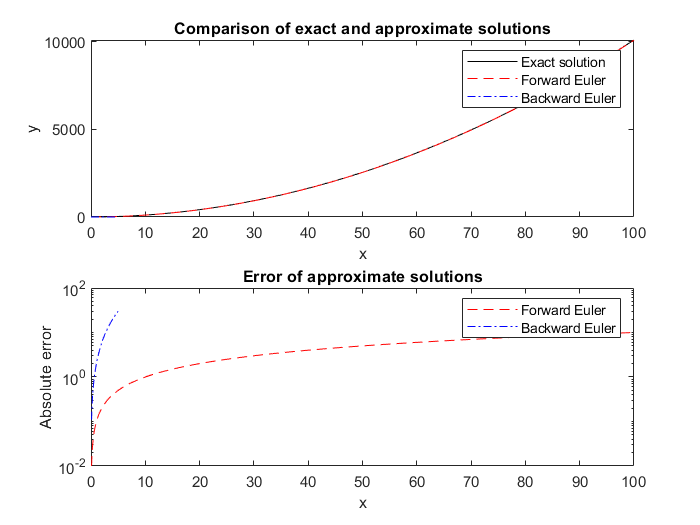

% Define the ODE and its initial condition
f = @(x, y) 2 * x + 1;
y0 = 0;

% Define the exact solution
y_exact = @(x) x.*(x+1);

% Define the time interval and step size
t_start = 0;
t_end = 100;
h = 0.1;
tspan = t_start:h:t_end;

% Use Forward Euler method to approximate the solution
tic
y_forward = zeros(size(tspan));
y_forward(1) = y0;
for i = 2:length(tspan)
    y_forward(i) = y_forward(i-1) + h * f(tspan(i-1), y_forward(i-1));
end
time_forward = toc;

% Use Backward Euler method to approximate the solution
tic
y_backward = zeros(size(tspan));
y_backward(1) = y0;
for i = 2:length(tspan)
    y_backward(i) = y_backward(i-1) / (1 - 2 * h * tspan(i-1));
end
time_backward = toc;

% Calculate the error between the exact and approximate solutions
error_forward = abs(y_exact(tspan) - y_forward);
error_backward = abs(y_exact(tspan) - y_backward);

% Plot the results
figure
subplot(2,1,1)
plot(tspan, y_exact(tspan), 'k-', tspan, y_forward, 'r--', tspan, y_backward, 'b-.')
title('Comparison of exact and approximate solutions')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')

subplot(2,1,2)
semilogy(tspan, error_forward, 'r--', tspan, error_backward, 'b-.')
title('Error of approximate solutions')
legend('Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('Absolute error')


% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_forward);

Time taken for Forward Euler method: 0.005366 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_backward);

Time taken for Backward Euler method: 0.011952 seconds


## **Second-order ODE:**

y'' + y = sin(x), y(0) = 0, y'(0) = 1

**Exact solution:**

y(x) = 1/2 (3 sin(x) - x cos(x))

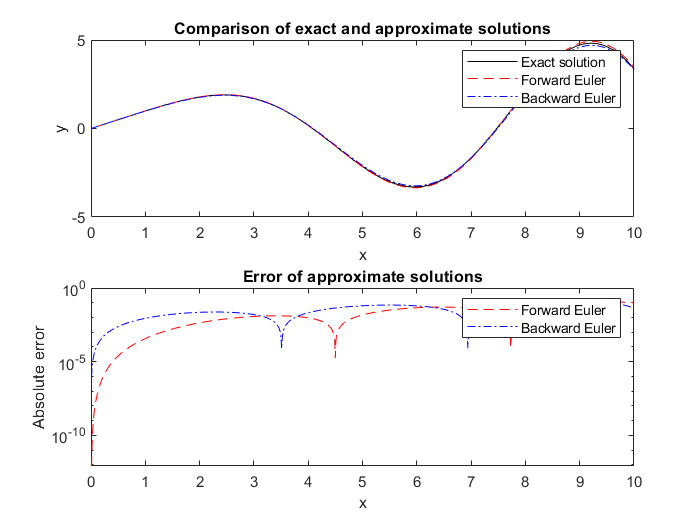

% Define the ODE and its initial conditions
f = @(x, y) [y(2); sin(x) - y(1)];
y0 = [0; 1];

% Define the exact solution
y_exact = @(x) 1/2 * (3.*sin(x) - x.*cos(x));

% Define the time interval and step size
t_start = 0;
t_end = 10;
h = 0.01;
tspan = t_start:h:t_end;

% Use Forward Euler method to approximate the solution
tic
y_forward = zeros(length(y0), length(tspan));
y_forward(:,1) = y0;
for i = 2:length(tspan)
    y_forward(:,i) = y_forward(:,i-1) + h * f(tspan(i-1), y_forward(:,i-1));
end
time_forward = toc;

% Use Backward Euler method to approximate the solution
tic
y_backward = zeros(length(y0), length(tspan));
y_backward(:,1) = y0;
for i = 2:length(tspan)
    y_backward(:,i) = (eye(length(y0)) - h * [0, 1; -1, 0]) \ y_backward(:,i-1) ...
        + h * [0; sin(tspan(i-1))];
end
time_backward = toc;

% Calculate the error between the exact and approximate solutions
error_forward = abs(y_exact(tspan) - y_forward(1,:));
error_backward = abs(y_exact(tspan) - y_backward(1,:));

% Plot the results
figure
subplot(2,1,1)
plot(tspan, y_exact(tspan), 'k-', tspan, y_forward(1,:), 'r--', tspan, y_backward(1,:), 'b-.')
title('Comparison of exact and approximate solutions')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')

subplot(2,1,2)
semilogy(tspan, error_forward, 'r--', tspan, error_backward, 'b-.')
title('Error of approximate solutions')
legend('Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('Absolute error')


% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_forward);

Time taken for Forward Euler method: 0.007061 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_backward);

Time taken for Backward Euler method: 0.011618 seconds


## **Third-order ODE:**

y''' + y'' + y' + y = 2x - 1, y(0) = 1, y'(0) = 0, y''(0) = 0

**Exact solution:**

y(x) = 2 x + 2 e^(-x) + 2 cos(x) - 3

% Define the ODE and its initial conditions
f = @(x, y) [y(2); y(3); -y(1)-y(2)-y(3)+2*x-1];
y0 = [1; 0; 0];

% Define the exact solution
y_exact = @(x) 2*x + 2*exp(-x) + 2*cos(x) - 3;

% Define the time interval and step size
t_start = 0;
t_end = 10;
h = 0.01;
tspan = t_start:h:t_end;

% Use Forward Euler method to approximate the solution
tic
y_forward = zeros(length(y0), length(tspan));
y_forward(:,1) = y0;
for i = 2:length(tspan)
    y_forward(:,i) = y_forward(:,i-1) + h * f(tspan(i-1), y_forward(:,i-1));
end
time_forward = toc;

% Use Backward Euler method to approximate the solution
tic
y_backward = zeros(length(y0), length(tspan));
y_backward(:,1) = y0;
for i = 2:length(tspan)
    y_backward(:,i) = (eye(length(y0)) - h * [0, 1, 0; 0, 0, 1; -1, -1, -1]) \ ...
        (y_backward(:,i-1) + h * [0; 0; 2*tspan(i-1)-1]);
end
time_backward = toc;

% Calculate the error between the exact and approximate solutions
error_forward = abs(y_exact(tspan) - y_forward(1,:));
error_backward = abs(y_exact(tspan) - y_backward(1,:));

% Plot the results
figure
subplot(2,1,1)
plot(tspan, y_exact(tspan), 'k-', tspan, y_forward(1,:), 'r--', tspan, y_backward(1,:), 'b-.')
title('Comparison of exact and approximate solutions')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')

subplot(2,1,2)
semilogy(tspan, error_forward, 'r--', tspan, error_backward, 'b-.')
title('Error of approximate solutions')
legend('Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('Absolute error')

% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_forward);

Time taken for Forward Euler method: 0.011381 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_backward);

Time taken for Backward Euler method: 0.016483 seconds


## **Fourth-order ODE:**

y'''' + 4y'' + 4y = 0, y(0) = 1, y'(0) = 0, y''(0) = 0, y'''(0) = -4

**Exact solution:**

y(x) = ((x - 1) sin(sqrt(2) x))/sqrt(2) + (x + 1) cos(sqrt(2) x)

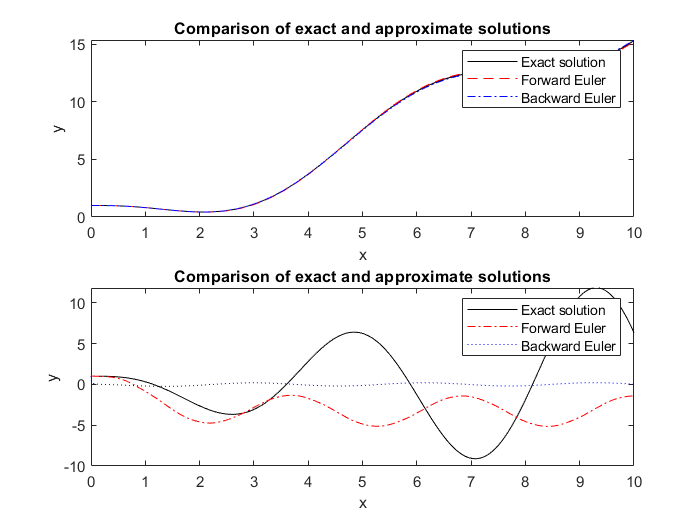

% Define the ODE
ode = @(x, y) [y(2); y(3); y(4); -4*y(2) - 4*y(3) - y(4)];

% Define the exact solution
exact_sol = @(x) ((x - 1) .* sin(sqrt(2) .* x))/sqrt(2) + (x + 1) .* cos(sqrt(2) .* x);

% Set the initial condition
y0 = [1; 0; 0; -4];

% Set the interval of integration
tspan = [0, 10];

% Set the tolerance
tol = 1e-6;

% Extract the solution of y(t)
y_ode45 = y(:, 1);

% Solve the ODE using Forward Euler method
h = 0.01;
y_fe = zeros(length(t), 1);
y_fe(1) = y0(1);

tic
for i = 1:length(t)-1
    y_fe(i+1) = y_fe(i) + h * (y(i, 2));
end
time_fe = toc;

% Solve the ODE using Backward Euler method
y_be = zeros(length(t), 1);
y_be(1) = y0(1);

tic
for i = 1:length(t)-1
    y_be(i+1) = (y_be(i) + h * (y(i, 2))) / (1 + 4 * h + 4 * h^2 + h^3);
end
time_be = toc;

% Plot the solutions
plot(t, exact_sol(t), 'k-', t, y_fe, 'r-.', t, y_be, 'b:')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')
title('Comparison of exact and approximate solutions')

subplot(2,1,2)
xlim([0.00 10.00])
ylim([-10.0 11.8])


% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_fe);

Time taken for Forward Euler method: 0.003988 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_be);

Time taken for Backward Euler method: 0.003193 seconds
